active_expt_index = 1;
current_binning_index = 1;

active_binning_resolution = across_experiment_results{active_expt_index}.processing_config.step_sizes{current_binning_index};
temp.curr_timestamps = across_experiment_results{active_expt_index}.timesteps_array{current_binning_index};
temp.curr_processed = across_experiment_results{active_expt_index}.active_processing.processed_array{current_binning_index};
active_results = across_experiment_results{active_expt_index}.results_array{current_binning_index};


% Unit Filtering:
filter_config.filter_included_cell_types = {'pyramidal'};
% filter_config.filter_included_cell_types = {'interneurons'};
filter_config.filter_maximum_included_contamination_level = {2};
[filter_config.filter_active_units, filter_config.original_unit_index] = fnFilterUnitsWithCriteria(across_experiment_results{active_expt_index}.active_processing, across_experiment_results{active_expt_index}.processing_config.showOnlyAlwaysStableCells, filter_config.filter_included_cell_types, ...
    filter_config.filter_maximum_included_contamination_level);
fprintf('Filter: Including %d of %d total units\n', sum(filter_config.filter_active_units, 'all'), length(filter_config.filter_active_units));

Filter: Including 68 of 126 total units



% Xcorr lag offsets are given by -9
% active_results.all.pairwise_xcorrelations.lag_offsets
% Find the range 200ms prior and after the 0 point.
temp.curr_xcorr_integration_range.lowerIndicies = find((0 >= active_results.all.pairwise_xcorrelations.lag_offsets) & (active_results.all.pairwise_xcorrelations.lag_offsets >= -0.2));
temp.curr_xcorr_integration_range.upperIndicies = find((0 <= active_results.all.pairwise_xcorrelations.lag_offsets) & (active_results.all.pairwise_xcorrelations.lag_offsets <= 0.2));

[temp.filtered.pre_sleep_REM_indicies] = fnFilterPeriodsWithCriteria(across_experiment_results{active_expt_index}.active_processing, {'pre_sleep'}, {'rem'}); % 668x1
[temp.filtered.post_sleep_REM_indicies] = fnFilterPeriodsWithCriteria(across_experiment_results{active_expt_index}.active_processing, {'post_sleep'}, {'rem'}); % 668x1

[temp.filtered.any_REM_indicies] = fnFilterPeriodsWithCriteria(across_experiment_results{active_expt_index}.active_processing, [], {'rem'}); % 668x1
temp.filtered.all_except_REM_indicies = ~temp.filtered.any_REM_indicies; % 668x1, the complement of the REM indicies


temp.results.any_REM.num_behavioral_periods = sum(temp.filtered.any_REM_indicies,'all');
temp.results.pre_sleep_REM.num_behavioral_periods = sum(temp.filtered.pre_sleep_REM_indicies,'all');
temp.results.post_sleep_REM.num_behavioral_periods = sum(temp.filtered.post_sleep_REM_indicies,'all');
fprintf('any_REM: %d periods\n pre_sleep_REM: %d periods\n post_sleep_REM: %d periods\n', temp.results.any_REM.num_behavioral_periods, temp.results.pre_sleep_REM.num_behavioral_periods, temp.results.post_sleep_REM.num_behavioral_periods);

any_REM: 23 periods
 pre_sleep_REM: 14 periods
 post_sleep_REM: 9 periods




temp.valid_pairs_reverse_lookup = across_experiment_results{active_expt_index}.general_results.indicies.reverse_lookup_unique_electrode_pairs(filter_config.filter_active_units, filter_config.filter_active_units);

## Testing Cell Offset Analysis

Benchmarking GPU-accelerated Cross-Correlation.



	**GPU not available. Stopping.**


## Single Pair Index:

active_pair_index =130

active_pair_index =    130




active_pair_unit_index = across_experiment_results{active_expt_index}.general_results.indicies.unique_electrode_pairs(active_pair_index,:)

active_pair_unit_index =      2     7


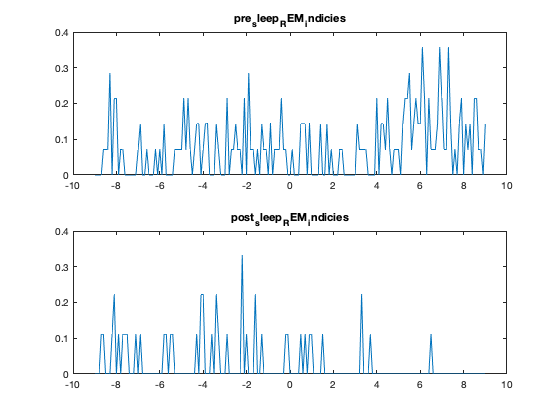


% reverse_lookup_unique_electrode_pairs
% active_results.by_behavioral_period.pairwise_xcorrelations.xcorr_full: num_of_behavioral_state_periods x num_unique_pairs x num_lag_steps] array


% Get the xcorr matrix for only this particular pair (indicated by active_pair_index):

temp.all.curr_xcorr_forPair = squeeze(active_results.all.pairwise_xcorrelations.xcorr(active_pair_index, :)); % for all behavioral periods (general)

% By behavioral state:
temp.by_behavioral_period.curr_xcorr_forPair = squeeze(active_results.by_behavioral_period.pairwise_xcorrelations.xcorr_full(:, active_pair_index, :)); % [num_of_behavioral_state_periods x num_lag_steps]

figure
subplot(2,1,1)
plot(active_results.all.pairwise_xcorrelations.lag_offsets, mean(temp.by_behavioral_period.curr_xcorr_forPair(temp.filtered.pre_sleep_REM_indicies, :),1));
title('pre_sleep_REM_indicies')
subplot(2,1,2)
plot(active_results.all.pairwise_xcorrelations.lag_offsets, mean(temp.by_behavioral_period.curr_xcorr_forPair(temp.filtered.post_sleep_REM_indicies, :),1));
title('post_sleep_REM_indicies')

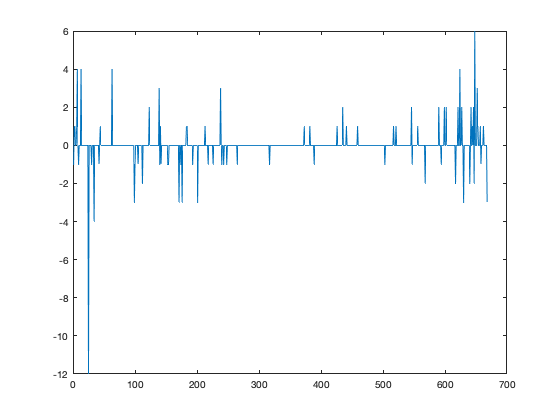



% Temporal Bias "B" as defined in SkaggsMcNaughtonScience1996.pdf:
% One for each behavioral period:
B = sum(temp.by_behavioral_period.curr_xcorr_forPair(:, temp.curr_xcorr_integration_range.upperIndicies),2) - sum(temp.by_behavioral_period.curr_xcorr_forPair(:, temp.curr_xcorr_integration_range.lowerIndicies), 2);

% For all: a scalar quantity:
% B = sum(temp.all.curr_xcorr_forPair(temp.curr_xcorr_integration_range.upperIndicies)) - sum(temp.all.curr_xcorr_forPair(temp.curr_xcorr_integration_range.lowerIndicies));

figure
plot(B)


% Pre-sleep:
B(temp.filtered.pre_sleep_REM_indicies)

ans =             0
            1
   2.0967e-16
  -1.0246e-16
            0
   1.8772e-16
           -1
   -2.473e-16
            0
   -3.595e-16



B(temp.filtered.post_sleep_REM_indicies)

ans =             0
            0
            0
            0
           -2
            0
            0
   6.2173e-17
   1.7625e-17



%active_results.by_behavioral_period.pairwise_xcorrelations.xcorr_all_periods = squeeze(mean(active_results.by_behavioral_period.pairwise_xcorrelations.xcorr_full, 1)); % [num_unique_pairs x num_lag_steps] array

% active_results.all.pairwise_xcorrelations.xcorr